**Define *****y***** as the following function: **$f(x) = $\sin^2{\frac{1}{x(2-x)}}$

Then the plot of the orginal function is shown to be:

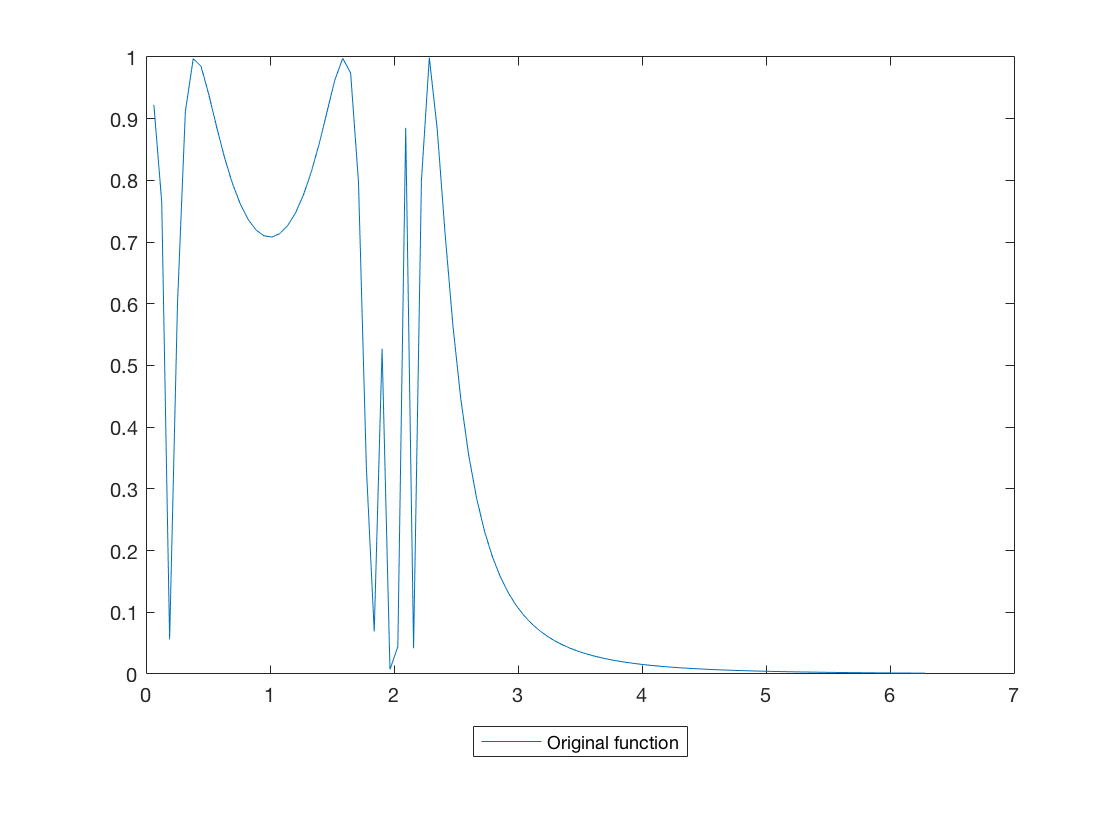

x = linspace(0,2*pi,100);
y = @(x) sin(1./(x.*(2-x))).^2;
plot(x,y(x))
legend('Original function','Location','southoutside')

***Forward/Backward*** **Difference** for the first derivative of function y:

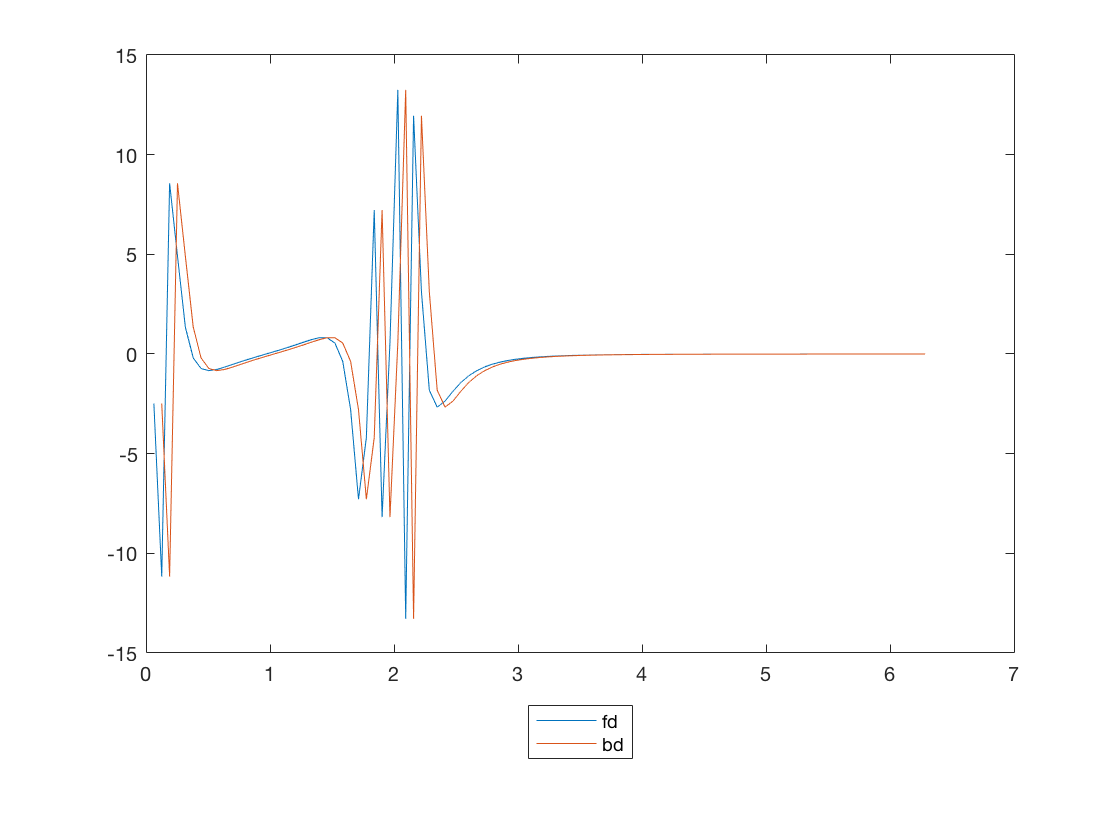

x = linspace(0,2*pi,100);
y = @(x) sin(1./(x.*(2-x))).^2; %you don't need to rewrite x and y again here
[dyf,dxf] = Der(y,x,'fd');
[dyb,dxb] = Der(y,x,'bd');

plot(dxf,dyf,dxb,dyb)

legend('fd','bd','Location','southoutside') %fd is forward and bd is backward

**Central Difference** for the first derivative:

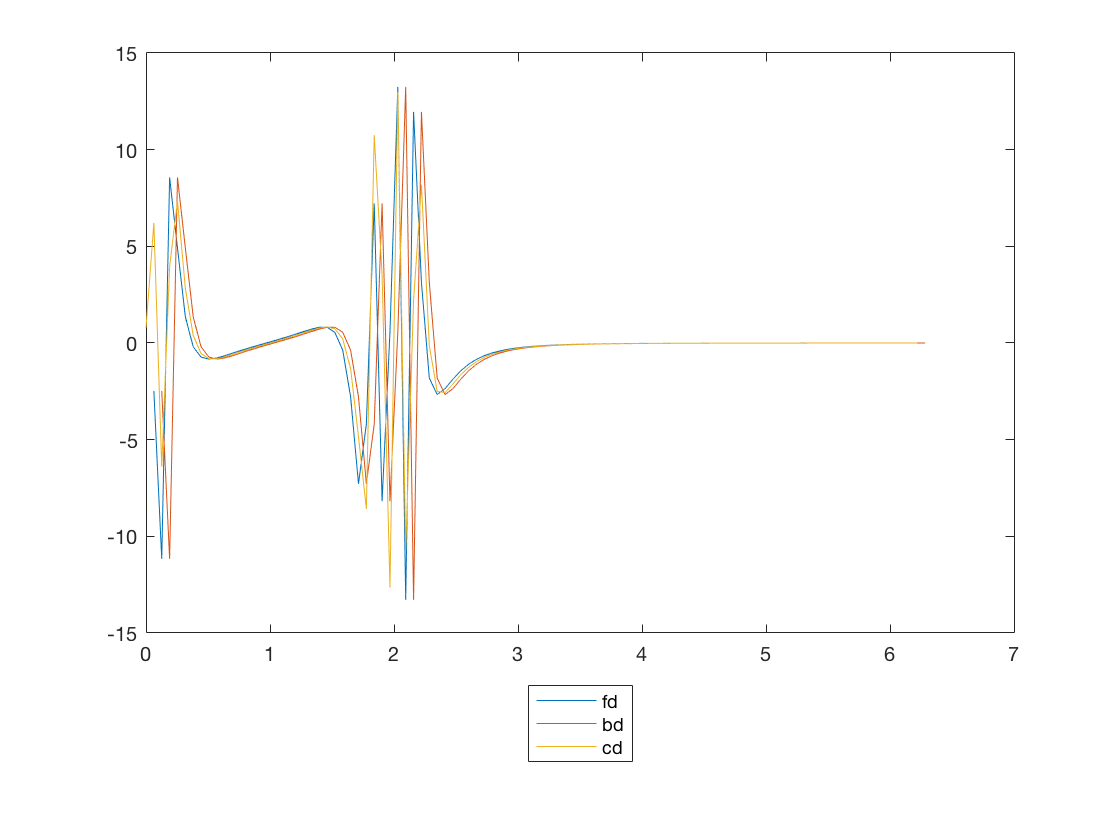

[dyf,dxf] = Der(y,x,'fd');
[dyb,dxb] = Der(y,x,'bd');
[dyc,dxc] = Der(y,x,'cd');
plot(dxf,dyf,dxb,dyb,dxc,dyc)

legend('fd','bd','cd','Location','southoutside')

Now, including the *higher order approximation* for the first derivative, specifically for the *cubic approximation*: 

Using the, "Der," function to find the derivative.

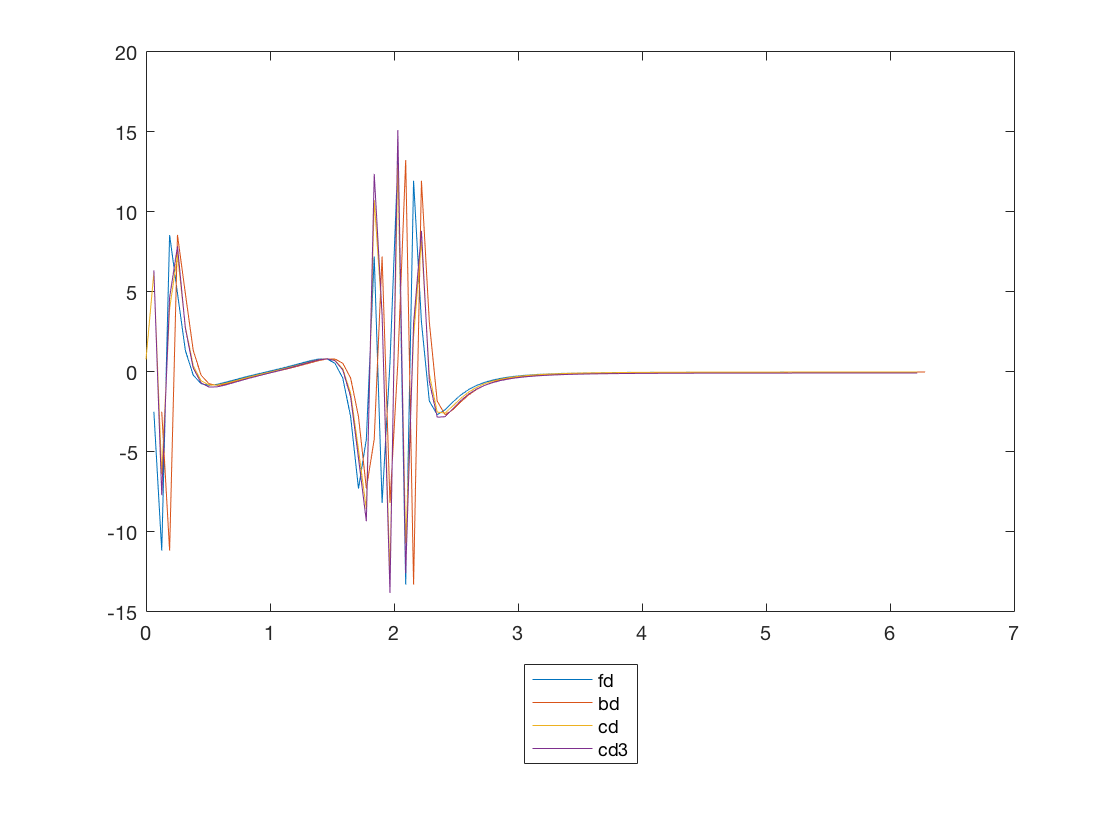

[dyf,dxf] = Der(y,x,'fd');
[dyb,dxb] = Der(y,x,'bd');
[dyc,dxc] = Der(y,x,'cd');
[dyc3,dxc3] = Der(y,x,'cd3');
plot(dxf,dyf,dxb,dyb,dxc,dyc,dxc3,dyc3)

legend('fd','bd','cd','cd3','Location','southoutside')

***Forward/Backward*** **Difference** for the second derivative of function y:

Since Der function returns the first derivative only, in order to find the second derivative, simply use the same function twice:

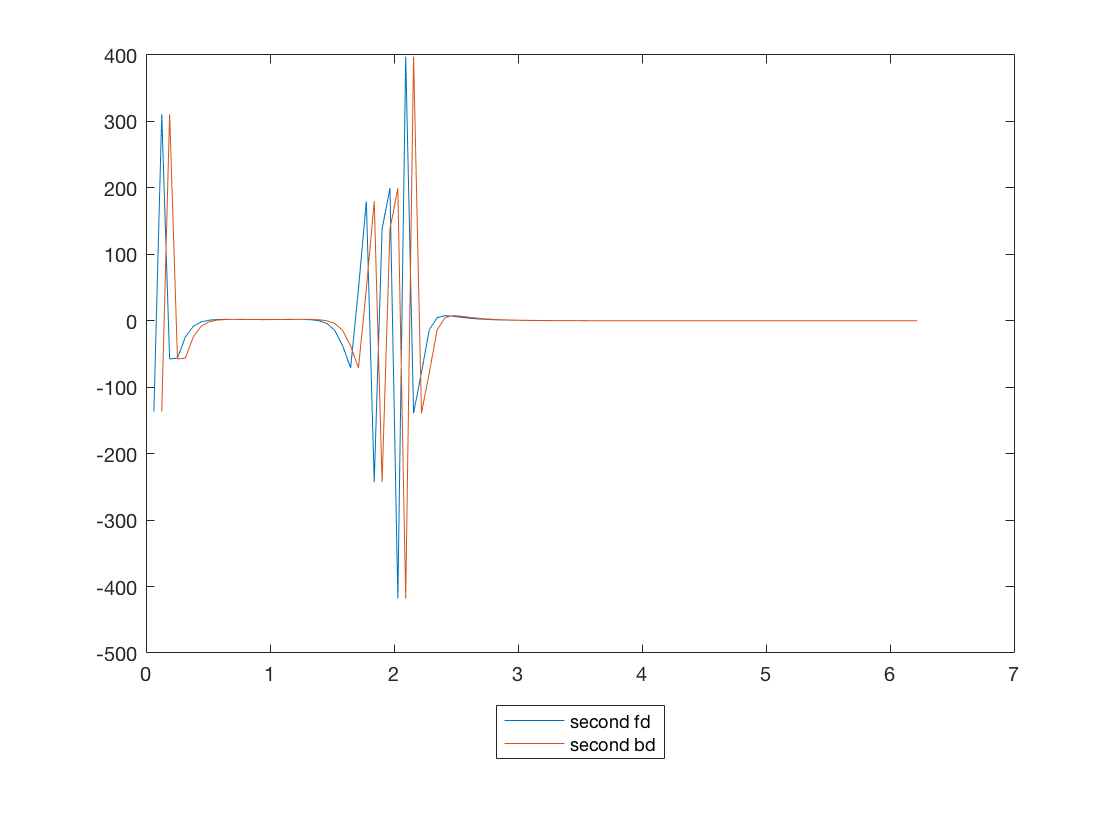

[dyfsec,dxfsec] = Der(dyf,dxf,'fd'); %second derivatives
[dybsec,dxbsec] = Der(dyb,dxb,'bd');
% [dycsec,dxcsec] = Der(dyc,dxc,'cd');
% [dysec3,dxsec3] = Der(dyc3,dxc3,'cd3');
plot(dxfsec,dyfsec,dxbsec,dybsec)
% dxcsec,dycsec,dxsec3,dysec3)
legend('second fd','second bd','Location','southoutside')

**Central Difference** for the* second derivative* as well as the cubic approximation: 

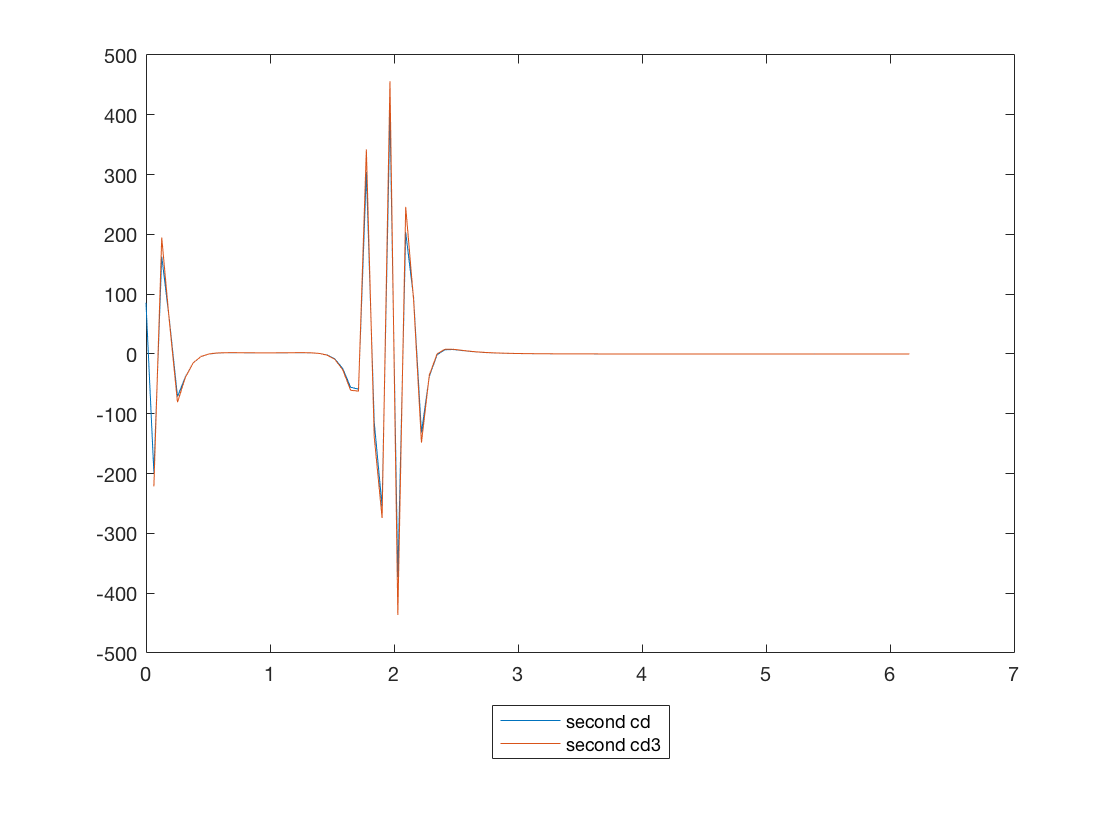

[dycsec,dxcsec] = Der(dyc,dxc,'cd');
[dysec3,dxsec3] = Der(dyc3,dxc3,'cd3');
plot(dxcsec,dycsec,dxsec3,dysec3)
legend('second cd','second cd3','Location','southoutside')

Imporing data from another file called, "derdata.m" and plotting them:

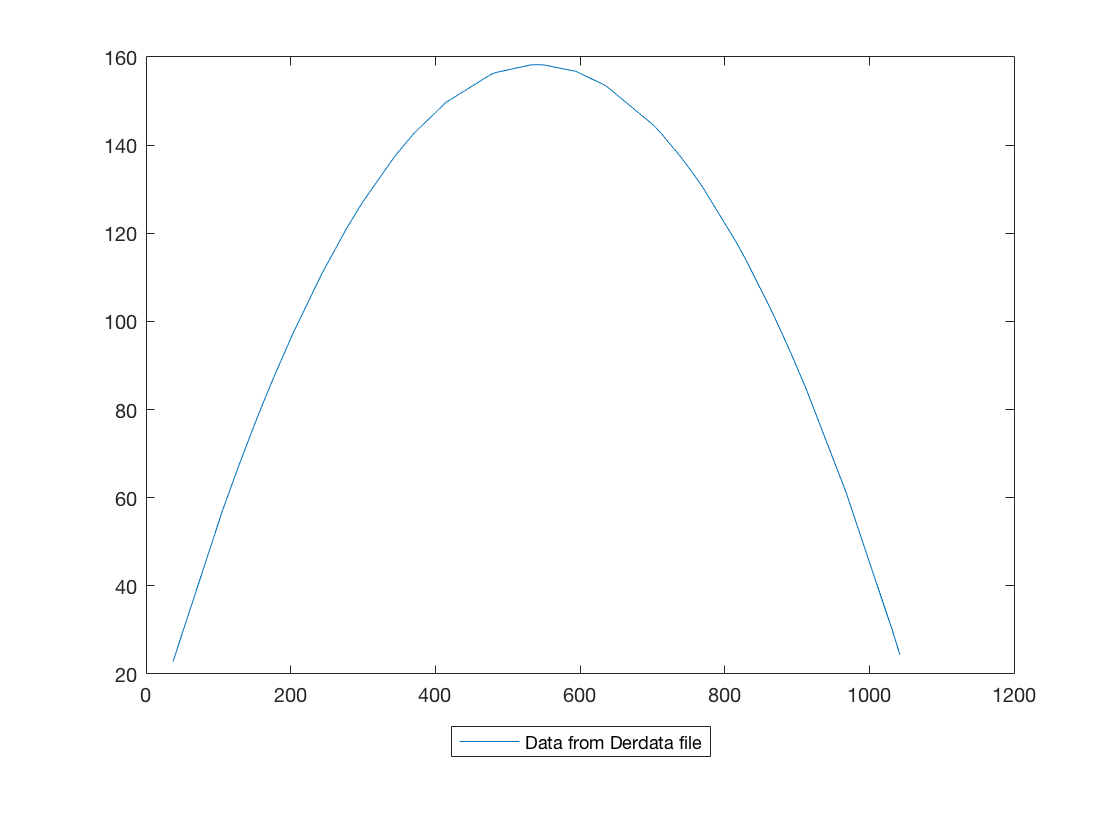


filename= 'derdata.mat'; 
myVars= {'X','Y'}; %bringing my data
S= load(filename,myVars{:}); %Create a Structurearray tht filled with your x and y
% to access x and y we use S.X and S.Y
plot(S.X,S.Y)
legend('Data from Derdata file','Location', 'southoutside')

**Forward/Backward/Central Difference **for the *first and second derivative* of the new data:

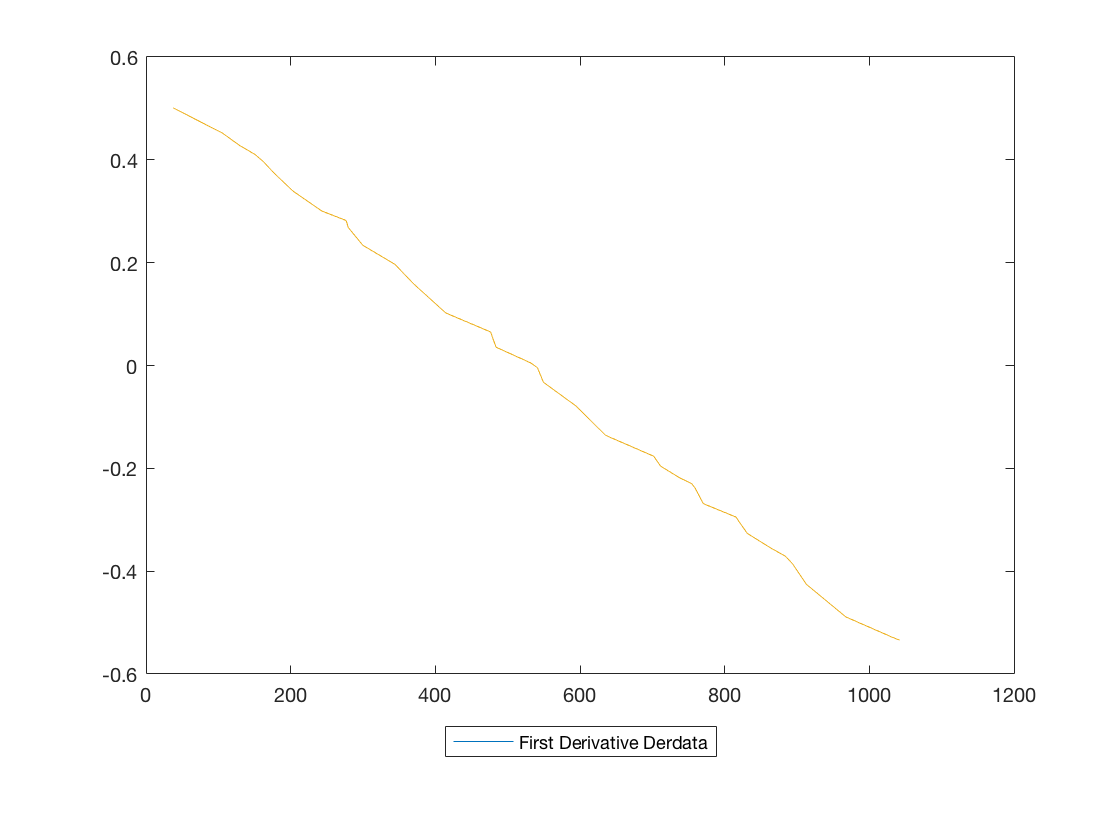

%First derivative
[deryf,derxf] = Der(S.Y,S.X,'fd'); %second derivatives
[deryb,derxb] = Der(S.Y,S.X,'bd');
[deryc,derxc] = Der(S.Y,S.X,'cd');
[deryc3,derxc3] = Der(S.Y,S.X,'cd3');
plot(derxf,deryf,derxb,deryb,derxc,deryc)
legend('First Derivative Derdata','Location','southoutside')

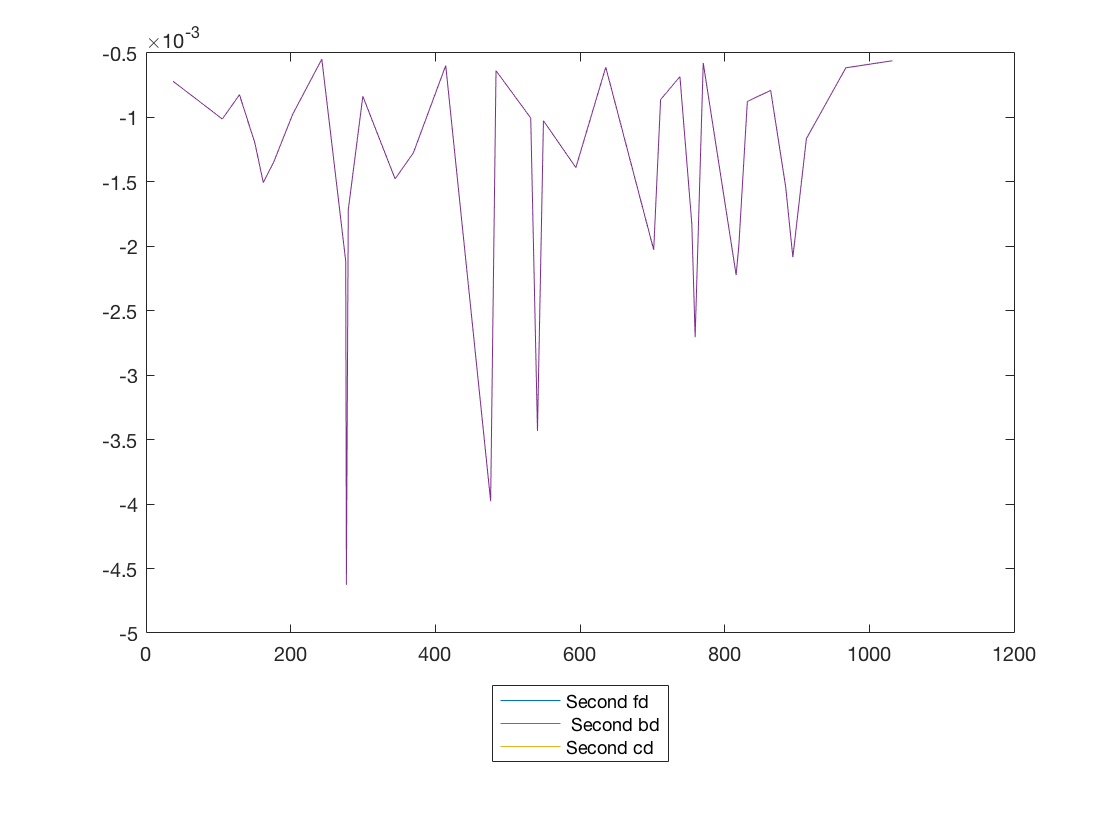


%Second derivative
[deryfsec,derxfsec]= Der(deryf,derxf,'fd'); %the slope is constant therefore the derivative is zero if you zoom out (change range) the plot would look like a horizontal line
[derybsec,derxbsec]= Der(deryb,derxb,'bd');
[derycsec,derxcsec]= Der(deryc,derxc,'cd');
[derycsec3,derxcsec3]= Der(deryc3,derxc3,'cd3');
plot(derxfsec,deryfsec,derxbsec,derybsec,derxcsec,derycsec,derxcsec3,derycsec3);
legend ('Second fd',' Second bd','Second cd','Location','southoutside')

We can change the range  of the y-axis to "zoom out" and show that the second derivative is actually a horizontal line:

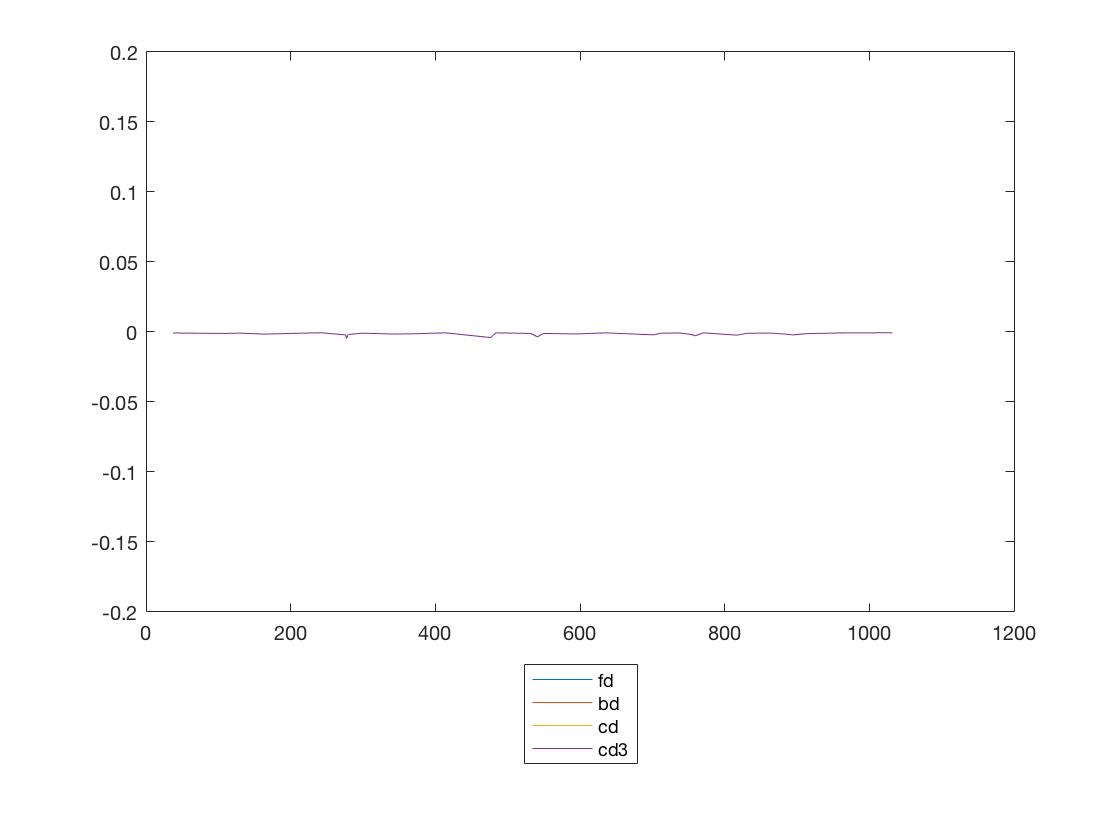

%Second derivative
[deryfsec,derxfsec]= Der(deryf,derxf,'fd'); %the slope is constant therefore the derivative is zero if you zoom out (change range) the plot would look like a horizontal line
[derybsec,derxbsec]= Der(deryb,derxb,'bd');
[derycsec,derxcsec]= Der(deryc,derxc,'cd');
[derycsec3,derxcsec3]= Der(deryc3,derxc3,'cd3');
plot(derxfsec,deryfsec,derxbsec,derybsec,derxcsec,derycsec,derxcsec3,derycsec3);
ylim([-0.2 0.2])
legend ('fd','bd','cd','cd3','Location','southoutside')